# 仿真数据后处理

## 读取数据

clear;
clc;

#### 剖面数据

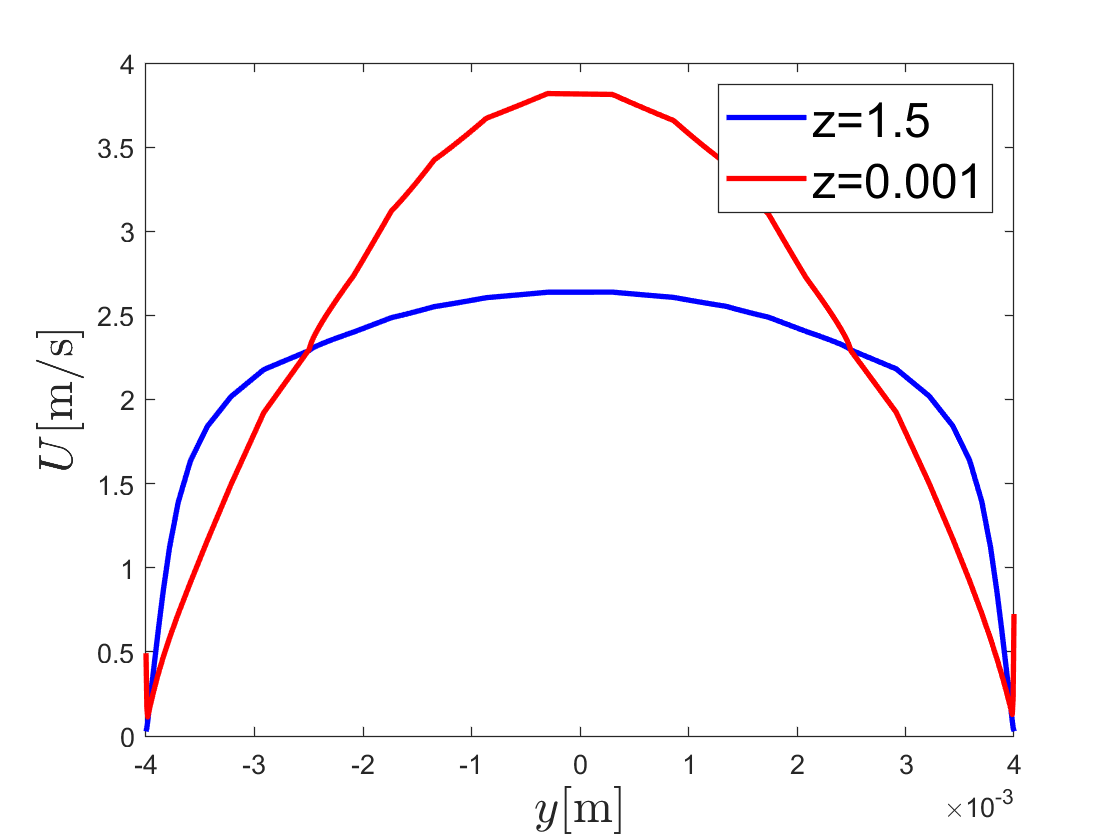


[data,head,all]=xlsread("C:\Users\admin\Desktop\pipeflow\pipeflow_L2200D8_ds0.01_200_SA_U4\z=1.5.csv");
[data1,title1,all1]=xlsread("C:\Users\admin\Desktop\pipeflow\pipeflow_L2200D8_ds0.01_200_SA_U4\z=0.001.csv");
xyz=data(:,1:3);
Uxyz=data(:,5:7);
UMag=data(:,8);
xyz1=data1(:,1:3);
Uxyz1=data1(:,5:7);
UMag1=data1(:,8);

figure
plot(xyz(:,2),UMag,'-b','LineWidth',2);hold on;
plot(xyz1(:,2),UMag1,'-r','LineWidth',2);
% ti=title("Velocity Profile");
% ti.FontSize=18;
lg=legend("z=1.5","z=0.001");
lg.FontSize=18;
xlabel('$y$[m]','interpreter','latex', 'FontSize', 18);
ylabel('$U$[m/s]','interpreter','latex', 'FontSize', 18);

#### 压强数据%OpenFoam是单位密度的压强，Fluent是实际压强

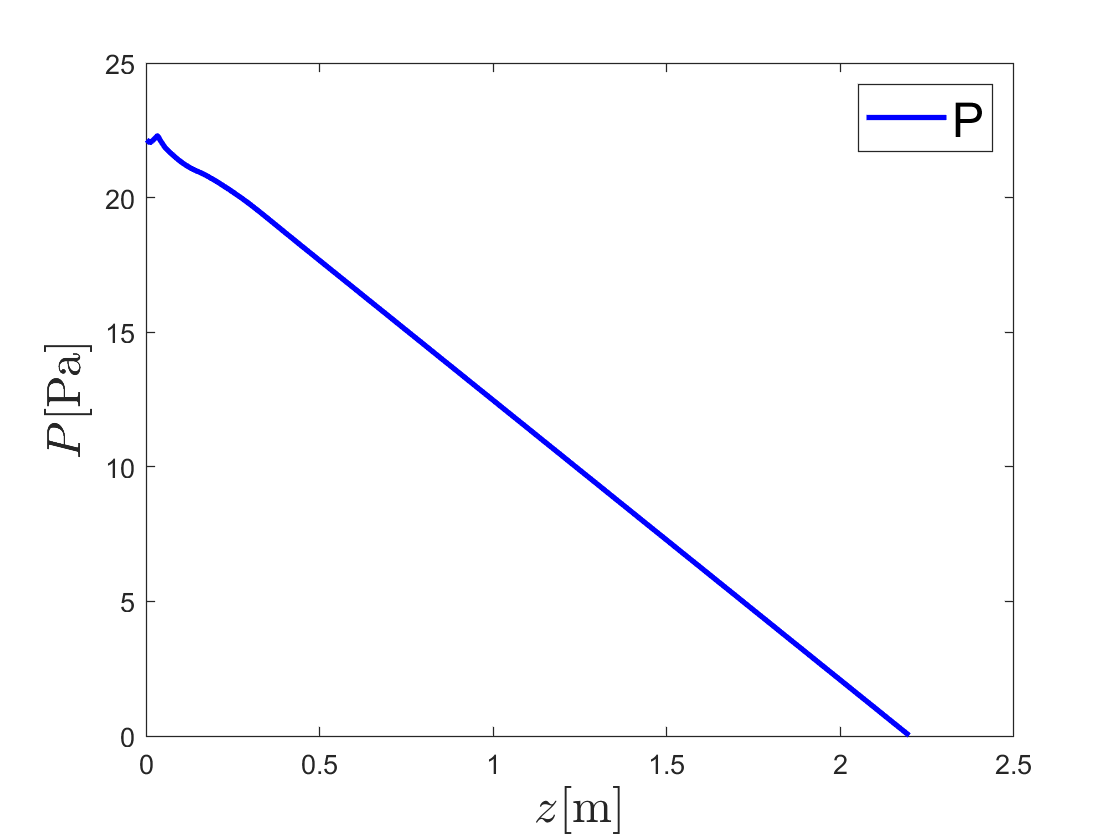

[data,head,all]=xlsread("C:\Users\admin\Desktop\pipeflow\pipeflow_L2200D8_ds0.01_200_SA_U4\xy=0.csv");
xyz=data(:,1:3);
Uxyz=data(:,5:7);
UMag=data(:,8);
P=data(:,12);
figure
plot(xyz(2:end,3),P(2:end),'-b','LineWidth',2);
lg=legend("P");
lg.FontSize=18;
xlabel('$z$[m]','interpreter','latex', 'FontSize', 18);
ylabel('$P$[Pa]','interpreter','latex', 'FontSize', 18);

#### 根据压强计算摩擦因子

rho=1065;
Um=2;
L=1;
d=0.008;
mu=0.004;
Re=rho*Um*d/mu;
lambda=(P(365)-P(820))/(0.5*Um^2*L/d);
lambda1=64/Re;
lambda2=0.3164/(Re^(0.25));

#### 切应力

% [data,head,all]=xlsread("C:\Users\admin\Desktop\pipeflow\pipeflow_L2200D8_ds0.01_turbulent_SA\x=-0.004.csv");
% xyz=data(:,1:3);
% Uxyz=data(:,5:7);
% UMag=data(:,8);
% wallshear=data(:,15:18);
% figure
% plot(xyz(365:820,3),wallshear(365:820,1),'-b','LineWidth',2);hold on;
% plot(xyz(365:820,3),wallshear(365:820,2),'-b','LineWidth',2);hold on;
% plot(xyz(365:820,3),wallshear(365:820,3),'-b','LineWidth',2);hold on;
% plot(xyz(365:820,3),wallshear(365:820,4),'-b','LineWidth',2);
% lg=legend("wallshear1","wallshear2","wallshear3","wallshear4");
% lg.FontSize=18;
% xlabel('$z$[m]','interpreter','latex', 'FontSize', 18);
% ylabel('wallshear[Pa]', 'FontSize', 18);


## 输出数据